close all; clear; clc;

# MEGA 2 blade STv4

record all points

**file name**: STv4_1_4bat_MEGA27d2b_20181205.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
diameter = 27 /12;
radius = diameter/2;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_1_4bat_MEGA27d2b_20181205.mat');
time1 = STv4_1_4bat_MEGA27d2b_20181205(:,1);                       % [sec]
PWM1 = STv4_1_4bat_MEGA27d2b_20181205(:,2);                        % [micro sec]
Q1 = STv4_1_4bat_MEGA27d2b_20181205(:,4);                          % [ft.lbf]
T1 = STv4_1_4bat_MEGA27d2b_20181205(:,5);                          % [lbf]
Input_V1 = STv4_1_4bat_MEGA27d2b_20181205(:,6);                    % [Volts]
Input_A1 = STv4_1_4bat_MEGA27d2b_20181205(:,7);                    % [Amps]
rot_speed_rpm1 = STv4_1_4bat_MEGA27d2b_20181205(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1 = rot_speed_rpm1 .* (pi/30);   % [rad/sec]
P_in_W1 = STv4_1_4bat_MEGA27d2b_20181205(:,9);                     % [Watts]
P_out_W1 = STv4_1_4bat_MEGA27d2b_20181205(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                  % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff1 = STv4_1_4bat_MEGA27d2b_20181205(:,11);                 % [%]
Prop_Eff1 = STv4_1_4bat_MEGA27d2b_20181205(:,12);                  % [lbf/Watts]
Overall_Eff1 = STv4_1_4bat_MEGA27d2b_20181205(:,13);               % [lbf/Watts]  
ESC_Temp1 = STv4_1_4bat_MEGA27d2b_20181205(:,14);                  % [F]
Motor_Temp1 = STv4_1_4bat_MEGA27d2b_20181205(:,15);                % [F]

disk_loading1 = T1 ./ area;                     % [lb/sq.ft]

Settling_time1 = STv4_1_4bat_MEGA27d2b_20181205(:,17); % [s]
Max_Acc1 = STv4_1_4bat_MEGA27d2b_20181205(:,18);      % [RPM]

throttle1 = (PWM1 - 1000) ./ 10;

## Thrust, Power, and Torque Coefficents

C_T1 = T1 ./ (p .* area * (rot_speed_rad1 * radius).^2);
C_P1 = P_out1 ./ (p .* area .* (rot_speed_rad1 .* radius).^3);
C_Q1 = Q1 ./ (p .* area .* (rot_speed_rad1 .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

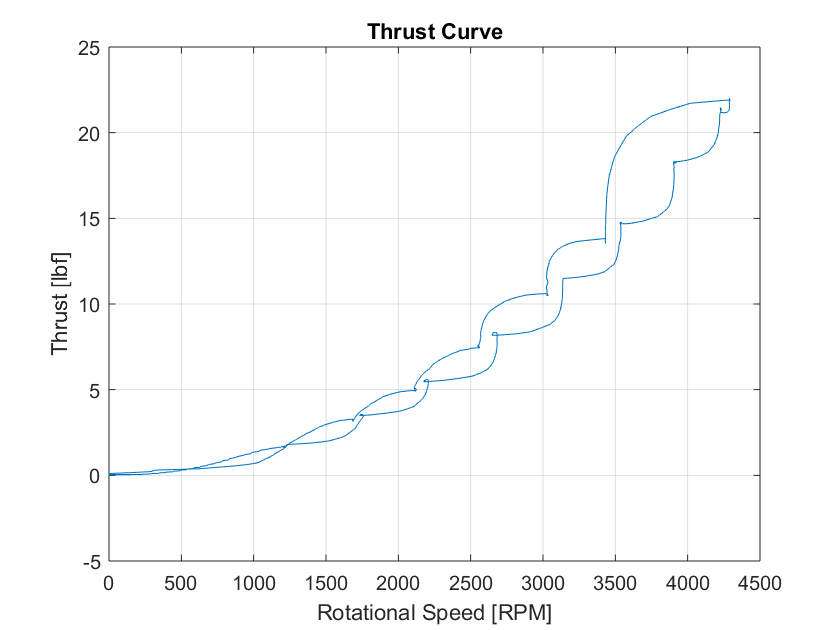

figure(1)
plot(rot_speed_rpm1, T1); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

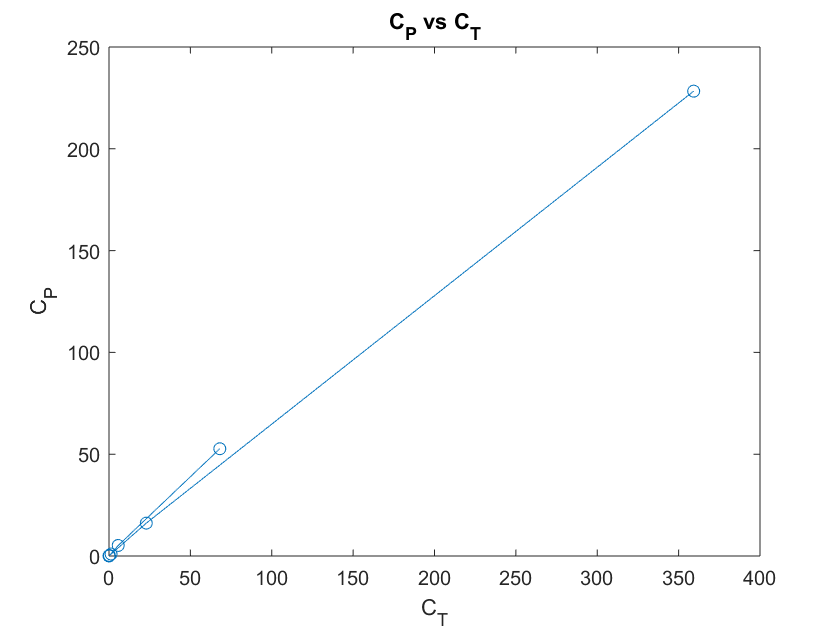


figure(2)
plot(C_T1, C_P1,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

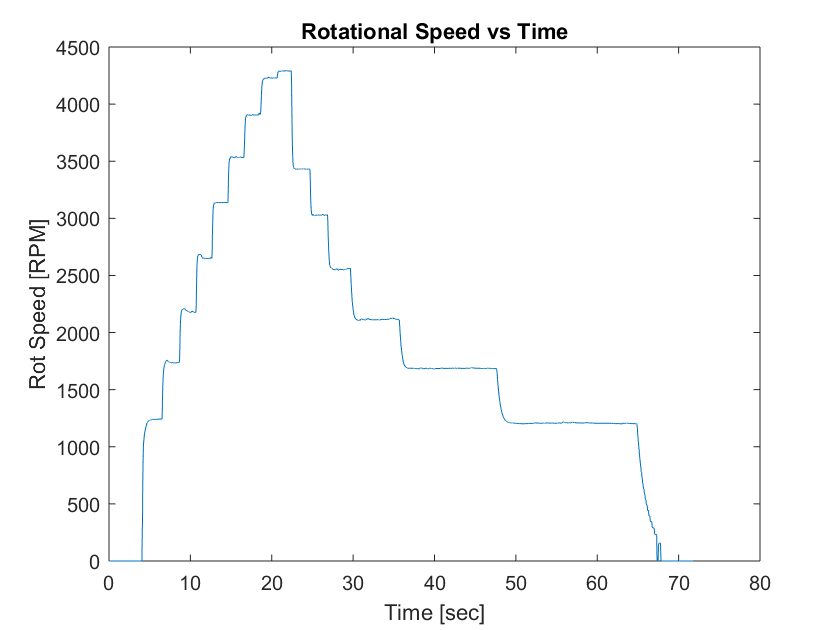


figure(3)
plot(time1, rot_speed_rpm1); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

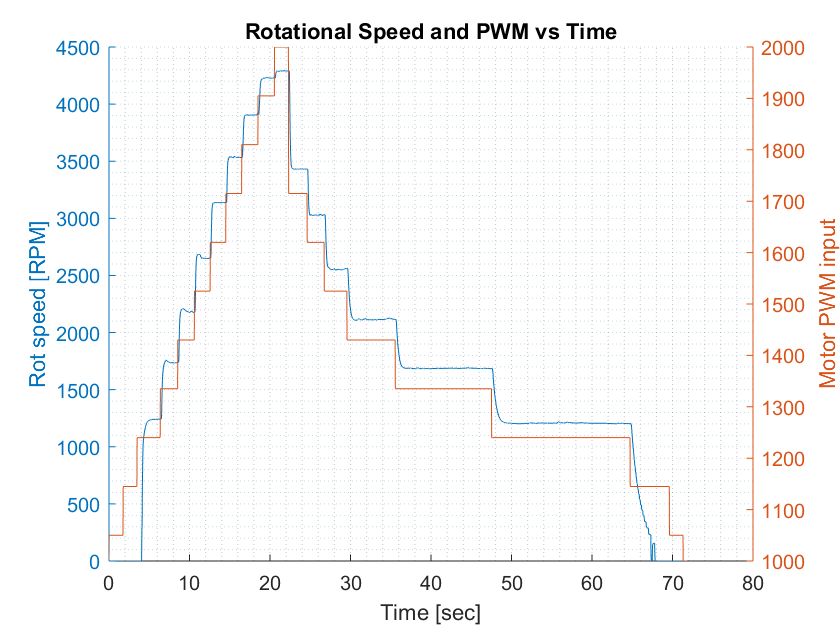


figure(4)
hold on
yyaxis left
plot(time1, rot_speed_rpm1);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time1, PWM1);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

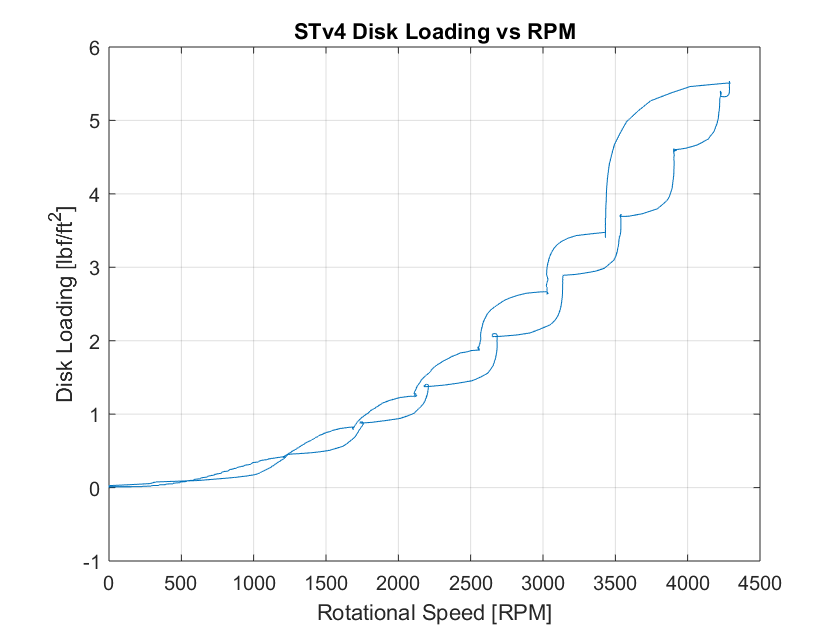


figure(5)
plot(rot_speed_rpm1, disk_loading1); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

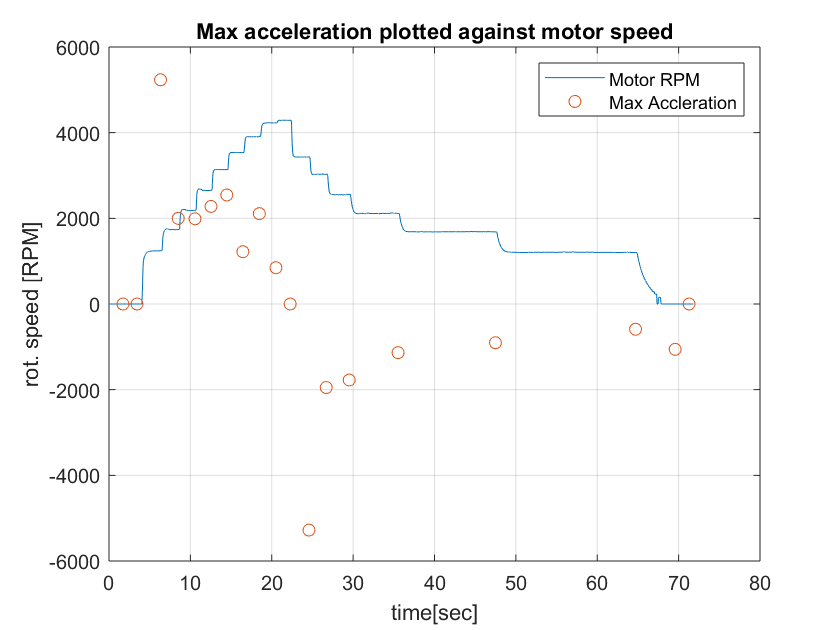



figure(6)
plot(time1, rot_speed_rpm1, time1, Max_Acc1, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

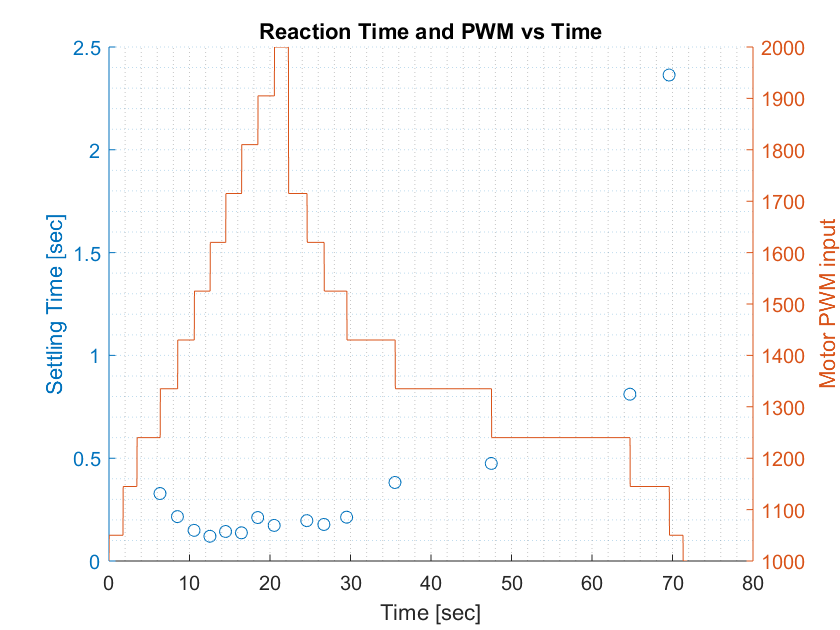


figure(7)
hold on
yyaxis left
plot(time1,Settling_time1, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time1, PWM1);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

## Comparing Data to Momentum Theory

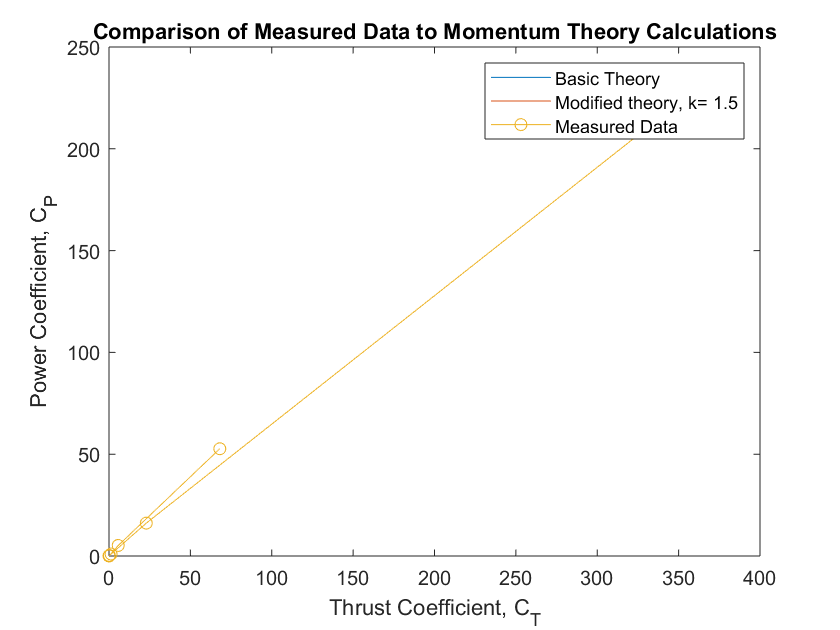

k = 1.15;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T1, C_P1, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data')